# Data Analytics: Boxplots and normal distributions

#### by Rodolfo Muñoz

clear variables; close all; clc;

First we start by letting the user select the file.

[filename,path] = uigetfile('*.xls;*xlsx');
colors = [0.4 0.5 1; 0 0 0];

Then, we load the data into a datastore in case its a big file and select to read only one sheet at a time. Then we preview the table to select the data we need for the analysis. 

tabds = datastore([path filename],'Type',"spreadsheet");
tabds.ReadSize = 'sheet';
preview(tabds)

ans = 8×8 table
    seat_n     first_name       last_name      C1     C2    C3     C4    EX 
    ______    ____________    _____________    ___    __    ___    __    ___

      1       {'Kevin'   }    {'Alarcón'  }      7    4       6    7     5.1
      2       {'Fernanda'}    {'Bugueño'  }      4    4       7    5     3.8
      3       {'David'   }    {'Caballos' }      6    5       6    5     4.1
      4       {'Amanda'  }    {'Campusano'}    NaN    6       7    7     5.1
      5       {'Camila'  }    {'Castro'   }      4    5     NaN    4     5.1
      6       {'Victor'  }    {'Contreras'}      5    2       7    2     3.4
      7       {'Juan'    }    {'Correa'   }      6    5       6    6     4.6
      8       {'Fa

In this case, we have an example of an excel spreadsheet with student's grades from a scientific experiment. As such, each sheet has a list of the grades of each students from one class and a summary at the bottom end.

Given that we only want the raw data of the students grades, we erase the rows after the list of students ends.

i = 1;
while hasdata(tabds)
    tab = read(tabds);
    classes{i} = tab(1:find(isnan(tab.seat_n),1)-1,:);
    i = i+1;
end

Because of the nature of the experiment, we know that the data corresponds only to 2 classes: the control group and the experimental group, so we erase the extra null data.

classes = classes(1:2);

Finally we make the tables into arrays for easier manipulation in the following sections.

groups = {'Control', 'Experimental'};
tests = classes{1}.Properties.VariableNames(4:end);
grades = cell(1,length(classes));
for i = 1:length(grades)
    grades{i} = table2array(classes{i}(:,tests));
end

## Box plot

We'll draw 4-subplots with the data from the grades. On the top, two boxplots of the data from each class. On the bottom, a side-by-side comparisons of these *boxplots* and a *barplot* with the averages of each class and their difference in percentage. 

green = [0 0.75 0];
blue = [0.2 0.2 1];
f = figure('name','le box plots','units','normalized','outerposition',[0 0 1 1]);
    subplot(2,2,1)
boxplot(grades{1},'colors',green);
xticklabels(tests);
ylabel('Grades');
xlabel('Tests');
title(['Grades distribution of \color[rgb]{0 0.55 0}' groups{1} ' Group']);
    subplot(2,2,2)
boxplot(grades{2},'colors',blue);
xticklabels(tests);
ylabel('Grades');
xlabel('Tests');
title(['Grades distribution of \color[rgb]{0.2 0.2 1}' groups{2} ' Group']);

For the bottom half, we'll draw both boxplots side-by-side a boxplot for comparison 

we'll create an auxiliary array that contains the data from both classes intertwined with intercalated columns for each class.

L = max(size(grades{1},1), size(grades{2},1));
N = length(tests);
aux = nan(L,2*N);
aux(1:size(grades{1},1),1:2:end) = grades{1};
aux(1:size(grades{2},1),2:2:end) = grades{2};% 

Now a little trick wih the variable **pos** to make the spacing of the boxplots easily differentiable for each groups.

pos = 0:2*N-1; 
pos = pos + floor(pos/2);

And calculate the percentual differences

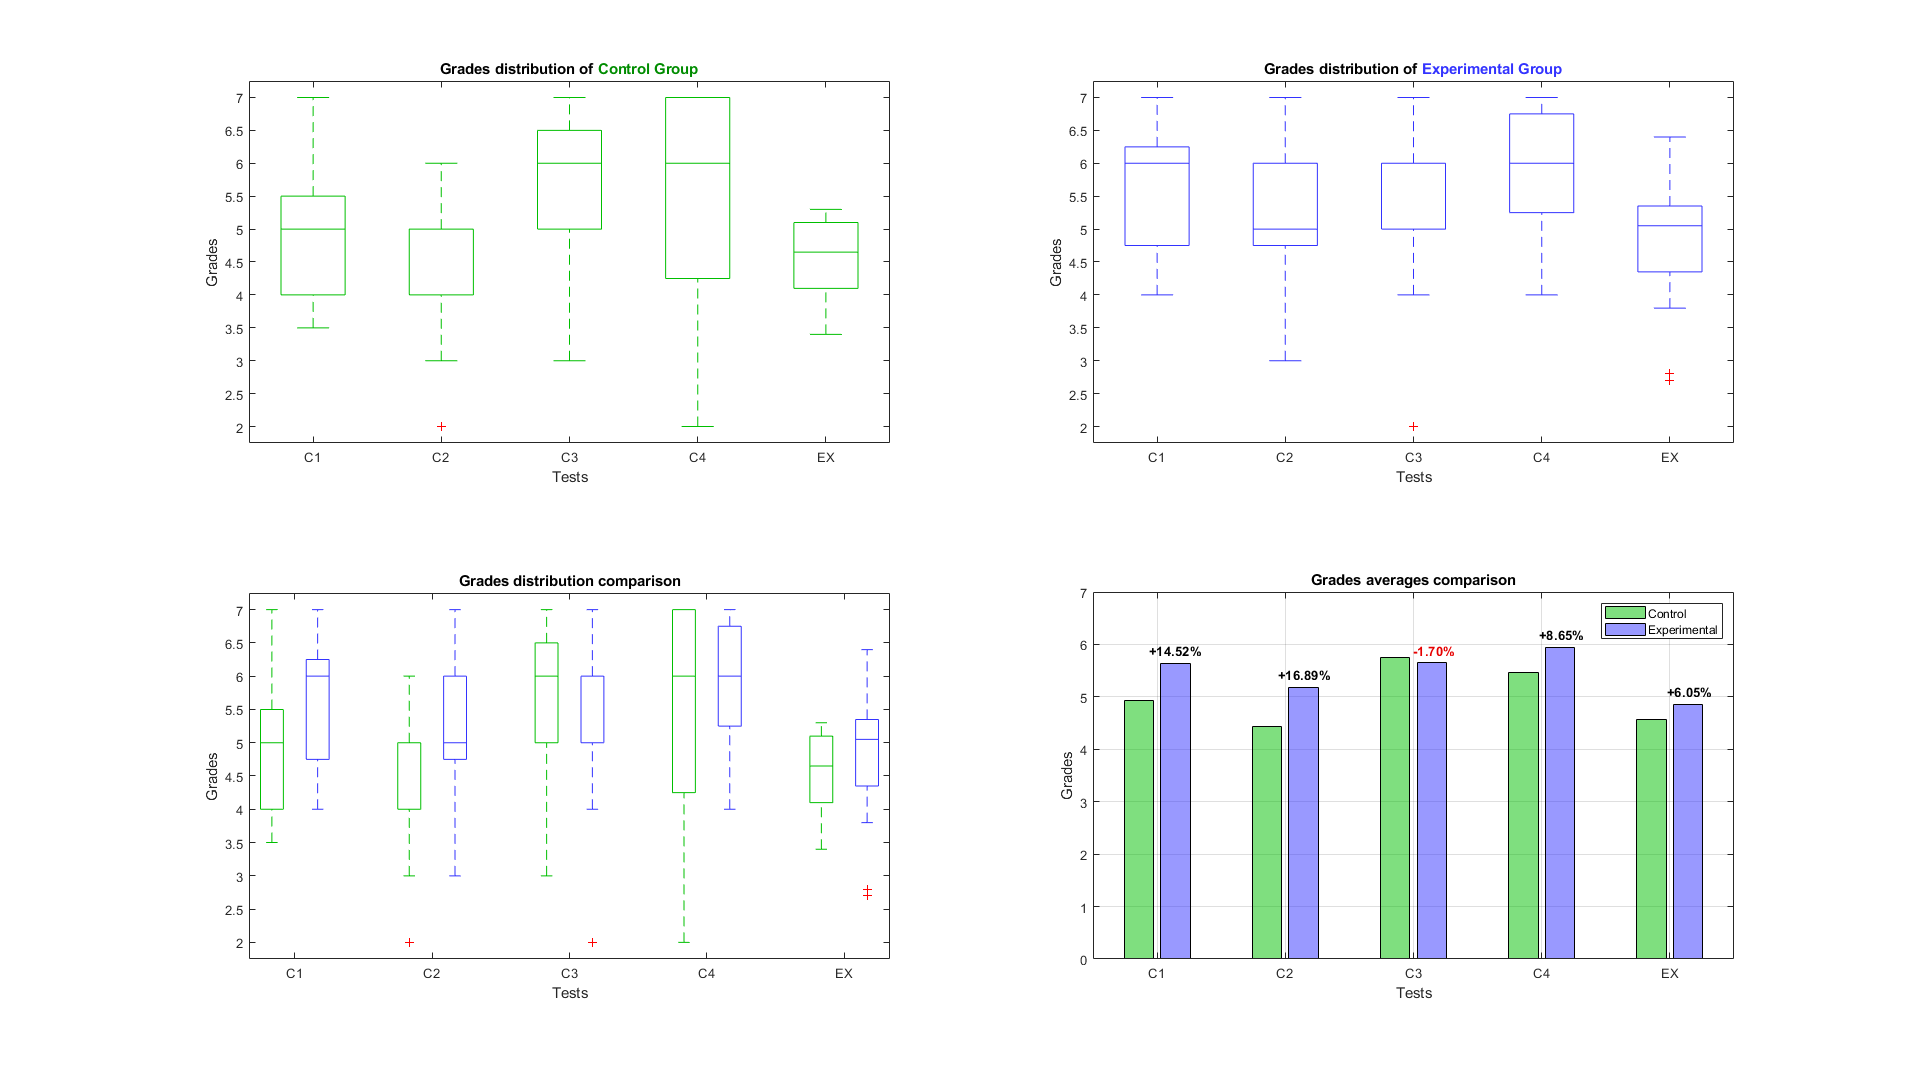

averages = nanmean(aux);
averages = [averages(1:2:end); averages(2:2:end)]';
delta = averages(:,2)-averages(:,1);
delta_p = round(delta./averages(:,1)*100,2);

    subplot(2,2,3)
boxplot(aux,'colors',[green;blue],'positions',pos);
xticks(0.5:3:pos(end));
xticklabels(tests);
ylabel('Grades');
xlabel('Tests');
title('Grades distribution comparison');
    subplot(2,2,4)
H = bar(averages,'FaceAlpha',0.5); 
hold on; grid on; 
T = text(H(2).XEndPoints, H(2).YEndPoints+0.25, num2str(delta_p,'%+5.2f%%'),...
      'HorizontalAlignment','center','FontWeight','bold');
hold off;
axis([0.5 5.5 0 7]);
set(H, {'FaceColor'}, {green; blue});
T(3).Color = [0.9 0 0];
xticklabels(tests);
ylabel('Grades');
xlabel('Tests');
legend(groups)%, 'Location','north'); %'northeastoutside');
title('Grades averages comparison')

## Histograms with normal distributions

Here we'll visualize the difference between the control group and the experimental group. For that, we'll fit normal distributions to the grades of each test with their means and standard deviations and draw the resulting normal curves as histograms overlaped one on top of the other.   

figure('name','le normals','units','normalized','outerposition',[0 0 1 1])
% binEdges = (0.75:0.5:7.5);
x = 0.5:0.1:7.5;
for i = 1:N-1
    subplot(3,2,i); hold on; grid on;
    pd1 = fitdist(grades{1}(:,i),'Normal');
    y = pdf(pd1,x);    
    bar(x,y,'facecolor',green,'facealpha',0.5);
    
    pd2 = fitdist(grades{2}(:,i),'Normal');
    y = pdf(pd2,x);
    bar(x,y,'facecolor',blue,'facealpha',0.5);
    
    axis([min(x) max(x) 0 1])
    legend({['\color[rgb]{0 0.55 0} \mu_C: ' num2str(round(pd1.mu,2)) '     \sigma_C: ' num2str(round(pd1.sigma,2))];...
           ['\color[rgb]{0.2 0.2 1} \mu_E: ' num2str(round(pd2.mu,2)) '     \sigma_E: ' num2str(round(pd2.sigma,2))]},...
           'FontWeight','bold', 'FontSize',12)
    title(tests{i})
end

Given that there are an even amount of plots, we'll draw the last one (EX) covering the whole row.

subplot(3,1,3); hold on; grid on;
pd1 = fitdist(grades{1}(:,end),'Normal');
y = pdf(pd1,x);
bar(x,y,'facecolor',green,'facealpha',0.5);

pd2 = fitdist(grades{2}(:,end),'Normal');
y = pdf(pd2,x);
bar(x,y,'facecolor',blue,'facealpha',0.5);
axis([min(x) max(x) 0 1])
legend({['\color[rgb]{0 0.55 0} \mu_C: ' num2str(round(pd1.mu,2)) '     \sigma_C: ' num2str(round(pd1.sigma,2))];...
    ['\color[rgb]{0.2 0.2 1} \mu_E: ' num2str(round(pd2.mu,2)) '     \sigma_E: ' num2str(round(pd2.sigma,2))]},...
    'FontWeight','bold', 'FontSize',12)
title(tests{end})

And finally, we add a title to the whole figure

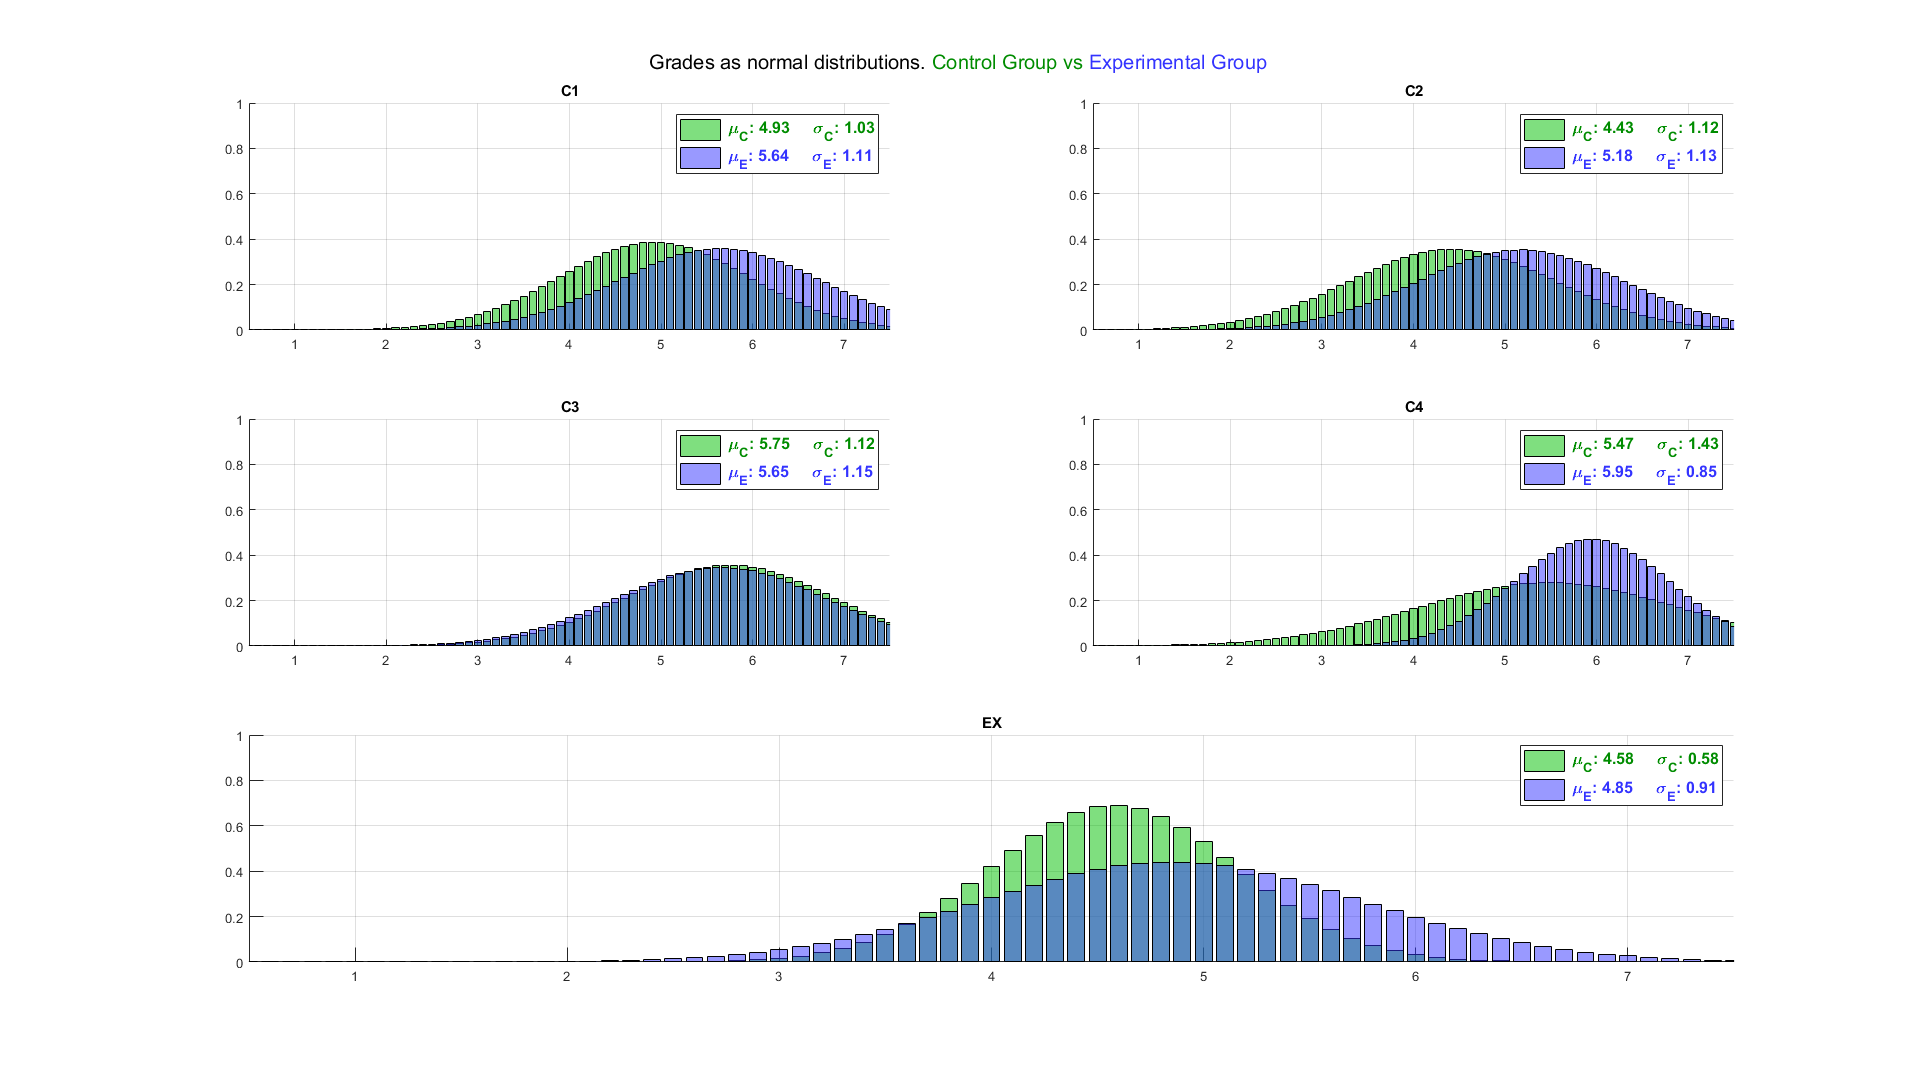

sgtitle(['Grades as normal distributions. \color[rgb]{0 0.55 0}' groups{1} ' Group vs \color[rgb]{0.2 0.2 1}' groups{2} ' Group'])